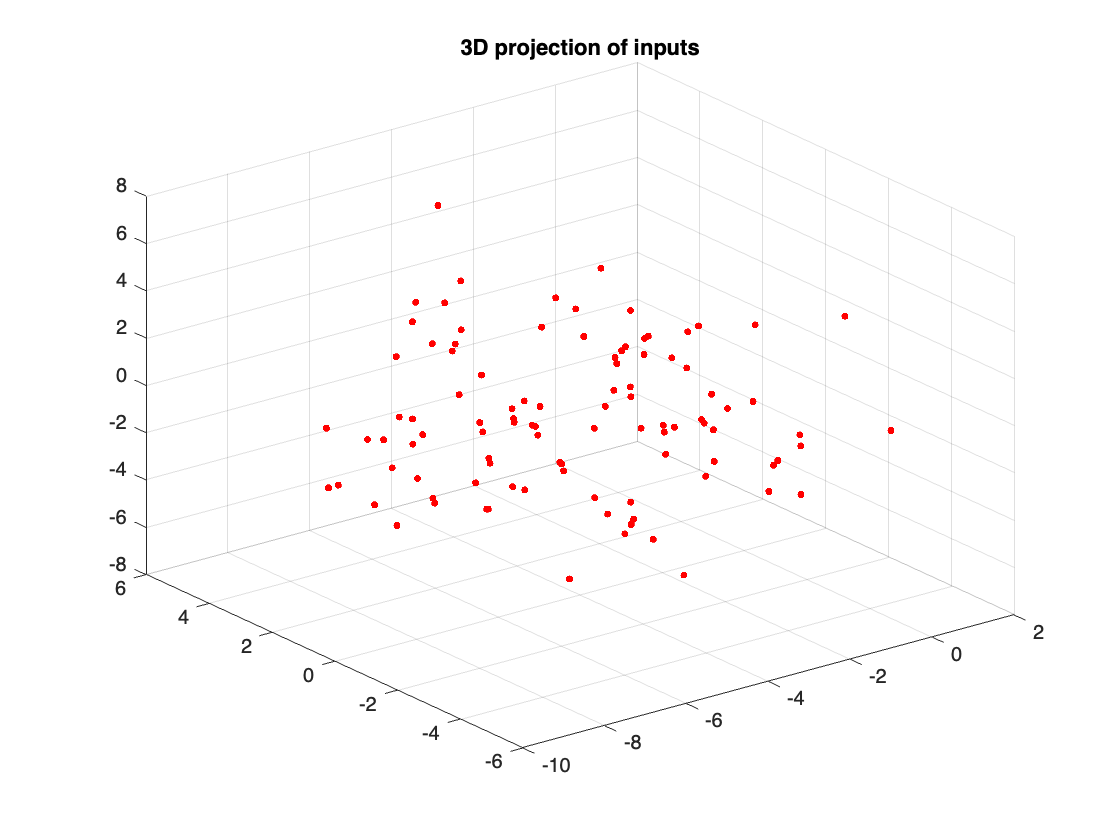

clear
format shortG
warning('off','all')
SetRNG(2);
dim = 30;
num = 100;
inputs = -5 + 6.*rand(num,dim);
data = inputs';


% pca on input data
coeff = pca(inputs);
Z=inputs*coeff(:,1:3);
figure;hold on
view(3);
plot3(Z(:,1),Z(:,2),Z(:,3),'r.','MarkerSize',10)
title('3D projection of inputs');
%legend('inputs','layer1 centroids','layer2 centroids','layer3 centroids','Location','NW')
grid on 
hold off


% clear all
% clc
% warning("off")
% load ('mnist.mat')
% num = 1000;
% colormap(gray(256))
% images = rescale(test.images(:,:,:),0,255);
% inputs = reshape(images,784,10000)';
% inputs = inputs(800:800+num,:);
% inputs = inputs - mean(inputs);
% data = inputs';
% dim = 784;


% generate synaptic weights

n_src = dim;
n_dst = 1;
n_per_src = round(dim*0.2);
synaptic_weights_mat = randn(n_src,n_dst);
[srcIdx,dstIdx] = ConnectHypergeometric(n_dst, n_src, n_per_src);
index = [srcIdx;dstIdx];
for i = 1:n_dst;
    nonzero_idx = index(2,find(index(1,:) == i));
    zero_idx = setdiff(1:n_src,nonzero_idx);
    synaptic_weights_mat(zero_idx,i) = 0;
end
cells = synaptic_weights_mat; %original
init = synaptic_weights_mat;

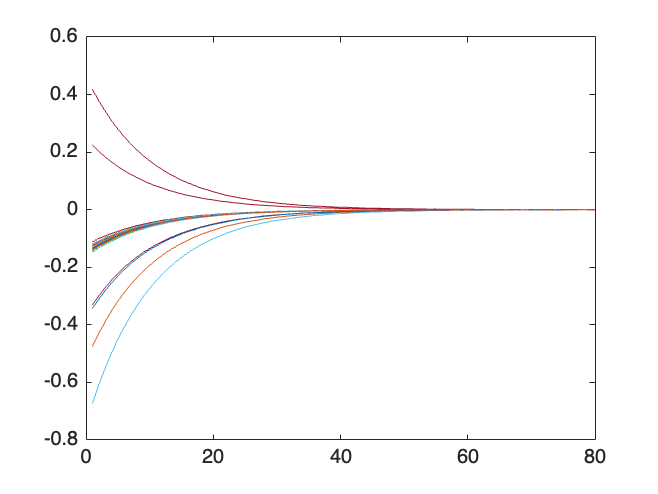

% cycle 1, find the cluster winners
cycle1_cells_iter = normc(cells);
iter_P = [];
iter_P_unfold =  [];
epoch = 80;
for k = 1:epoch;
    cycle1_winners = [];
    sampled_data = data(:, randperm(size(data, 2)));
    obj = mean(normc(sampled_data),2);
    winner_len_mat = [];
    winner_average = zeros(dim,1,n_dst);
    for col = 1:size(sampled_data,2); % loop over all inputs
        lr = 0.001;
        input1 = sampled_data(:,col);% each input
        len_input = norm(input1);
        input1 = normc(input1);
        updated_winningset = []; % in case of tied winners
        product = input1'*cycle1_cells_iter; % the dot products of the input and all cells
        winning_value = max(product); % max dot product value
        cell_idx = find(product == winning_value); % index(indices) of winning cell(s)
        cycle1_winners = [cycle1_winners;cell_idx];
        winner = cycle1_cells_iter(:,cell_idx);
        update_winner_ori = winner+(input1-winner)*lr; %update_winner_ori is NOT norm
        winner_average(:,:,cell_idx) = update_winner_ori + winner_average(:,:,cell_idx);
        cycle1_cells_iter(:,cell_idx) = update_winner_ori;
        iter_P_unfold = [iter_P_unfold,update_winner_ori];
    end
    current_P = winner_average./num;
    iter_P = [iter_P,current_P];
end



obj = mean(normc(sampled_data),2);
figure;
e = obj-iter_P;
plot(e')

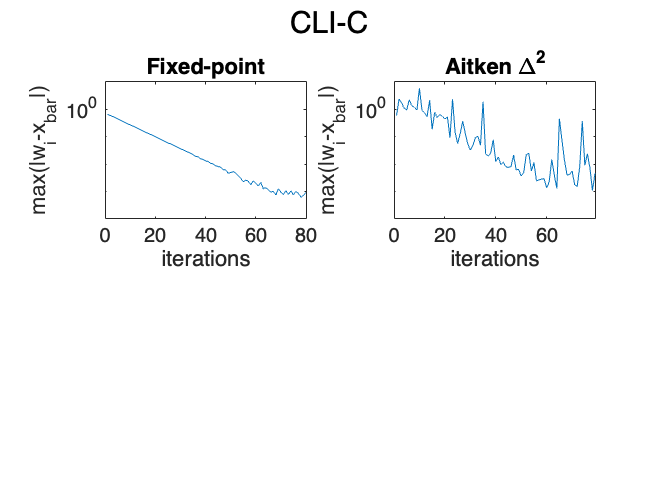


tilde_P = [];
delta_0 = init - ((iter_P(:,1)-init).^2)./(iter_P(:,2)-2.*iter_P(:,1)+init);
tilde_P = [tilde_P,delta_0];
for i = 1: size(iter_P,2)-2
    interim_P = iter_P(:,i) - (((iter_P(:,i+1)-iter_P(:,i)).^2)./(iter_P(:,i+2)-2.*iter_P(:,i+1)+iter_P(:,i)));
    interim_P = iter_P(:,i) - (((iter_P(:,i+1)-iter_P(:,i)).^2)./(iter_P(:,i+2)-2.*iter_P(:,i+1)+iter_P(:,i)));
    tilde_P = [tilde_P,interim_P];
end

tilde_P_unfold = [];
delta_0 = init - ((iter_P_unfold(:,1)-init).^2)./(iter_P_unfold(:,2)-2.*iter_P_unfold(:,1)+init);
tilde_P_unfold = [tilde_P_unfold,delta_0];
for i = 1: size(iter_P_unfold,2)-2
    interim_P = iter_P_unfold(:,i) - (((iter_P_unfold(:,i+1)-iter_P_unfold(:,i)).^2)./(iter_P_unfold(:,i+2)-2.*iter_P_unfold(:,i+1)+iter_P_unfold(:,i)));
    tilde_P_unfold = [tilde_P_unfold,interim_P];
end

% iter_P_new = [init,iter_P(:,1),iter_P(:,2)];
% S_P = [init - ((iter_P(:,1)-init).^2)./(iter_P(:,2)-2.*iter_P(:,1)+init)];
% for i = 2: size(iter_P,2)-2;
%     P1 = S_P(:,i-1) + 
% end

error_fix = max(abs(obj-iter_P));
error_delta = max(abs(obj-tilde_P));
error_fix_unfold = max(abs(obj-iter_P_unfold));
error_delta_unfold = max(abs(obj-tilde_P_unfold));
conv = (normc(obj)'*normc(iter_P))';
figure;
subplot(2,2,2)
semilogy(error_delta)
title('Aitken \Delta^2')
xlabel('iterations')
ylabel('max(|w_{i}-x_{bar}|)')
ylim([1e-4 10])
subplot(2,2,1)
semilogy(error_fix)
title('Fixed-point')
ylim([1e-4 10])
xlabel('iterations')
ylabel('max(|w_{i}-x_{bar}|)')
sgtitle('CLI-C') 

% subplot(2,2,4)
% semilogy(error_delta_unfold)
% title('Aitken \Delta^2 unfold')
% ylim([1e-4 10])
% subplot(2,2,3)
% semilogy(error_fix_unfold)
% title('Fixed-point unfold')
% ylim([1e-4 10])
% sgtitle('vectorized method') 

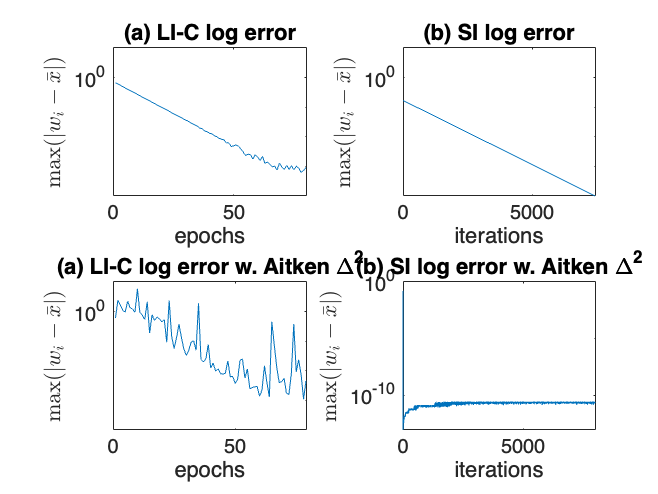

obj = mean(normc(sampled_data),2);
iter_P2 = [];
w = 0.0001*init;
for i = 1:8000;
    w = w+(obj-w)*lr;
    iter_P2 = [iter_P2,w];
end


tilde_P2 = [];
delta_0 = init - ((iter_P2(:,1)-init).^2)./(iter_P2(:,2)-2.*iter_P2(:,1)+init);
tilde_P2 = [tilde_P2,delta_0];
for i = 1: size(iter_P2,2)-2
    interim_P = iter_P2(:,i) - (((iter_P2(:,i+1)-iter_P2(:,i)).^2)./(iter_P2(:,i+2)-2.*iter_P2(:,i+1)+iter_P2(:,i)));
    tilde_P2 = [tilde_P2,interim_P];
end

error_fix2 = max(abs(obj-iter_P2));
error_delta2 = max(abs(obj-tilde_P2));
conv = (normc(obj)'*normc(iter_P2))';

figure;
subplot(2,2,3)
semilogy(error_delta)
title('(a) LI-C log error w. Aitken \Delta^2')
xlabel('epochs')
ylabel('$\max(|w_{i} - \bar{x}|)$', 'Interpreter', 'latex')
ylim([1e-4 10])
subplot(2,2,1)
semilogy(error_fix)
title('(a) LI-C log error')
ylim([1e-4 10])
xlabel('epochs')
ylabel('$\max(|w_{i} - \bar{x}|)$', 'Interpreter', 'latex')


subplot(2,2,4)
semilogy(error_delta2)
title('(b) SI log error w. Aitken \Delta^2')
xlabel('iterations')
ylabel('$\max(|w_{i} - \bar{x}|)$', 'Interpreter', 'latex')
subplot(2,2,2)
semilogy(error_fix2)
title('(b) SI log error')
ylim([1e-4 10])
xlabel('iterations')
ylabel('$\max(|w_{i} - \bar{x}|)$', 'Interpreter', 'latex')

% subplot(2,2,3)
% plot(conv)
% title('Cos similarity')

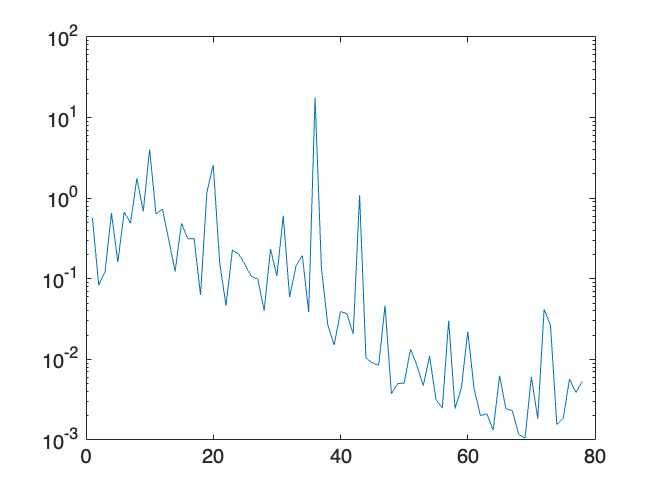

sequence1 = iter_P;
sequence2 = [];
for i = 2:size(sequence1,2);
    sequence2 = [sequence2,0.5*sequence1(:,i)+0.5*sequence1(:,i-1)];
end

init = synaptic_weights_mat;
tilde_P = [];

delta_0 = init - ((sequence2(:,1) - init).^2) ./ (sequence2(:,2) - 2 .* sequence2(:,1) + init);
tilde_P = [tilde_P, delta_0];

for i = 1:size(sequence2,2)-2
    interim_P = sequence2(:,i) - (((sequence2(:,i+1) - sequence2(:,i)).^2) ./ (sequence2(:,i+2) - 2 .* sequence2(:,i+1) + sequence2(:,i)));
    interim_P = sequence2(:,i) - (((sequence2(:,i+1) - sequence2(:,i)).^2) ./ (sequence2(:,i+2) - 2 .* sequence2(:,i+1) + sequence2(:,i)));
    tilde_P = [tilde_P, interim_P];
end
error_delta = max(abs(obj-tilde_P));
figure;
semilogy(error_delta)

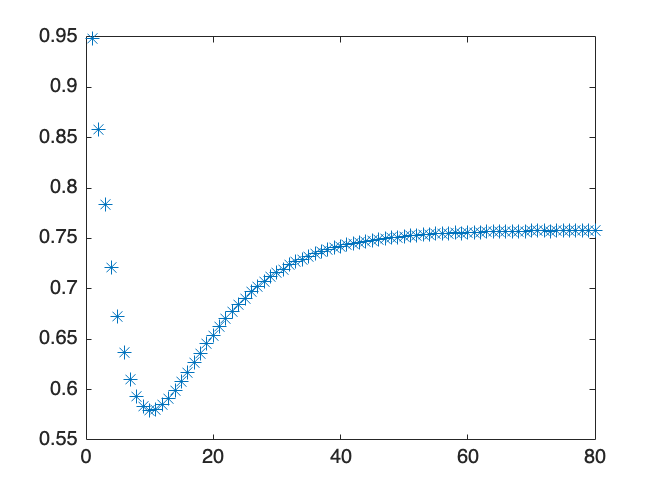


magnitudes1 = vecnorm(iter_P);
magnitudes2 = vecnorm(iter_P2);
plot(magnitudes1,"*")

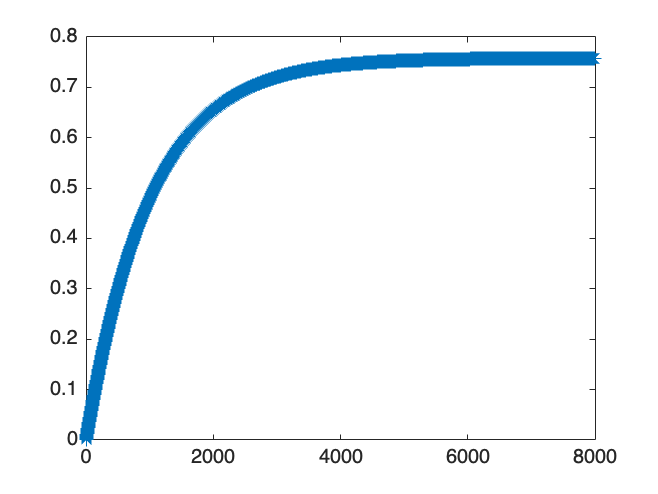

plot(magnitudes2,"*")